% demonstration code turned into live script
% constants replaced by variables when possible

clear variables
addpath(genpath(['./Library']))

dirpth='./Demo_dataset/';
fname_prefix='Block';

% get dimensions
image_info=imfinfo([dirpth, fname_prefix, num2str(1), '.tif']);
Nframes=numel(image_info); %OR [N,]=size(image_info)
xdim=image_info(1).Height;
ydim=image_info(1).Width;
clear image_info;

T=20;

## read images and calcualte M6 for each block

M6series = zeros(xdim, ydim, T);
ImMean_Series = zeros(xdim, ydim, T);
for blockN = 1 : T %for each block
    J = zeros(xdim, ydim, Nframes, 'uint16'); %create empty 3D array
    disp(['reading data and calculating M6 of block ',num2str(blockN),'/',num2str(T),'...'])
    for frameInd = 1 : Nframes %read all frames into the array
        J(:,:,frameInd) = imread(['./Demo_dataset/Block',num2str(blockN),'.tif'], 'Index', frameInd);
    end
    
    %   calculate average image for this block
    ImMean_Series(:, :, blockN) = mean(double(J), 3);
    
    %   calculate M6 of this block
    M6 = zeros(xdim, ydim);
    for i0 = 1 : Nframes
        M6 = M6 + (double(J(:, :, i0)) - ImMean_Series(:, :, blockN)).^6; % directly compute. 
    end
    M6 = M6./Nframes;
    M6series(:, :, blockN) = M6;
end

reading data and calculating M6 of block 1/20...
reading data and calculating M6 of block 2/20...
reading data and calculating M6 of block 3/20...
reading data and calculating M6 of block 4/20...
reading data and calculating M6 of block 5/20...
reading data and calculating M6 of block 6/20...
reading data and calculating M6 of block 7/20...
reading data and calculating M6 of block 8/20...
reading data and calculating M6 of block 9/20...
reading data and calculating M6 of block 10/20...
reading data and calculating M6 of block 11/20...
reading data and calculating M6 of block 12/20...
reading data and calculating M6 of block 13/20...
reading data and calculating M6 of block 14/20...
reading data and calculating M6 of block 15/20...
reading data and calculating M6 of block 16/20...
reading data and calculating M6 of block 17/20...
reading data and calculating M6 of block 18/20...
reading data and calculating M6 of block 19/20...
reading data and calculating M6 of block 20/20...


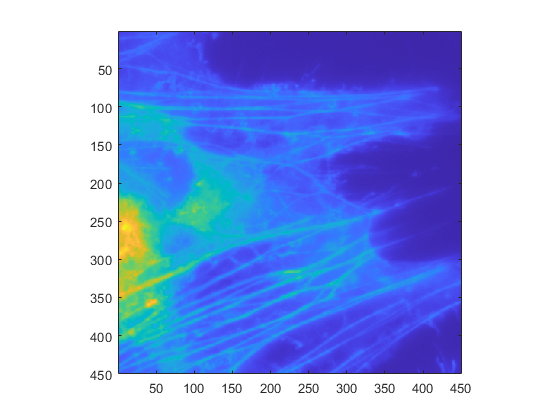


%show
figure('Name', 'ImMean')
imagesc(ImMean_Series(:,:,T))
axis square;

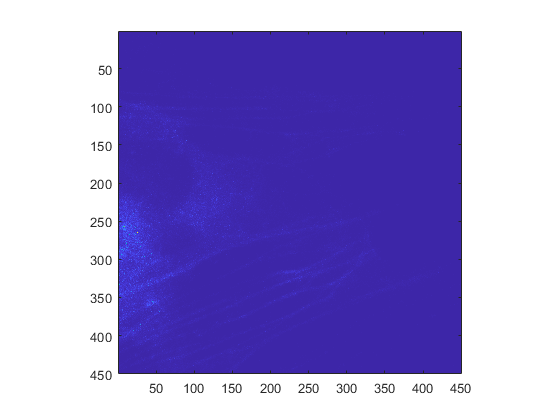

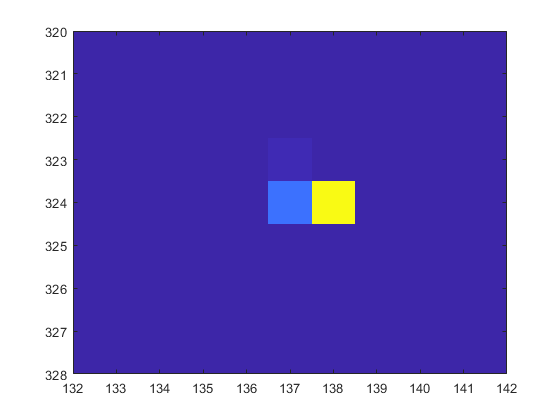

figure('Name', 'M6')
imagesc(M6series(:,:,T))
axis square;

## perform noise filter on M6 along the time axis for each pixel independently.

NF = fspecial('gaussian',[1,21],2); % define a noise filter. 

M6_filtered = zeros(xdim, ydim, T);
for i0 = 1:xdim
    for i1 = 1:ydim
        s = M6series(i0, i1, :); s = s(:); % take the time sequence
        s = conv(s,NF,'same'); % filter.
        M6_filtered(i0, i1, :) = reshape(s, [1, 1, T]); % store into the filtered variable
    end
end

## perform shrinking kernel deconvolution on M6 for each frame.

M6_NF_DeconvSK = zeros(xdim, ydim, T);
for blockN = 1 : T
    im = M6_filtered(:, :, blockN);
    % now prepare input parameters for xy_DeconvSk
    % perform mirror extension to the image in order to surpress ringing artifacts associated with fourier transform due to truncation effect.
    para.J0 = [im, fliplr(im); flipud(im), rot90(im,2)];
    % an estimation of the convolution kernel. In this datasets, cross-correlation doesn't work, therefore we use a rough estimation.
    para.PSF0 = fspecial('gaussian', [51,51], 2); 
    para.lambda = 1.5; %DeconvSK parameter
    para.ItN = 20; % iteration number.
    disp(['calculating DeconvSK on block ',num2str(blockN),'/',num2str(T),'...'])
    output = xy_DeconvSK(para);
    M6_NF_DeconvSK(:, :, blockN) = output(1:xdim, 1:ydim);
    clear output;
end

calculating DeconvSK on block 1/20...
calculating DeconvSK on block 2/20...
calculating DeconvSK on block 3/20...
calculating DeconvSK on block 4/20...
calculating DeconvSK on block 5/20...
calculating DeconvSK on block 6/20...
calculating DeconvSK on block 7/20...
calculating DeconvSK on block 8/20...
calculating DeconvSK on block 9/20...
calculating DeconvSK on block 10/20...
calculating DeconvSK on block 11/20...
calculating DeconvSK on block 12/20...
calculating DeconvSK on block 13/20...
calculating DeconvSK on block 14/20...
calculating DeconvSK on block 15/20...
calculating DeconvSK on block 16/20...
calculating DeconvSK on block 17/20...
calculating DeconvSK on block 18/20...
calculating DeconvSK on block 19/20...
calculating DeconvSK on block 20/20...


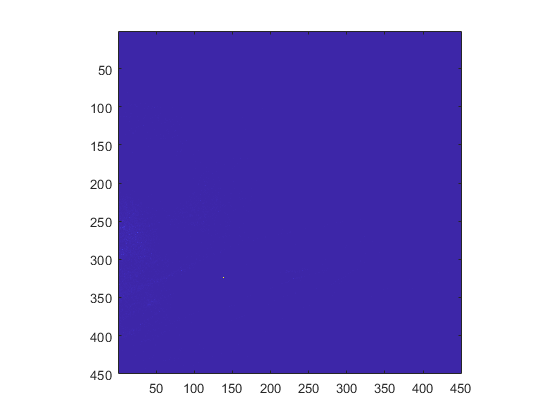


%figure
%imagesc(M6_NF_DeconvSK(:,:,T))
%axis square;

## perform then next round of noise filter to the deconvolution result

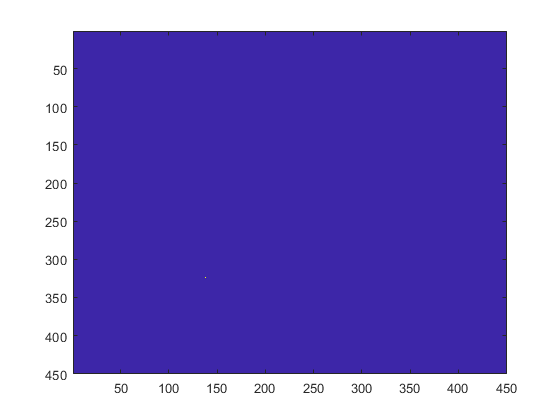

M6_NF_DeconvSK_NF = zeros(xdim, ydim, T);
for i0 = 1 : xdim
    for i1 = 1 : ydim
        s = M6_NF_DeconvSK(i0,i1,:); s = s(:);
        s = conv(s,NF,'same');
        M6_NF_DeconvSK_NF(i0,i1,:) = reshape(s,[1,1,T]);
    end
end

%figure
%imagesc(M6_NF_DeconvSK_NF(:,:,T))
%axis square;


## perform LDRC on the current result and save.

M6_LDRC = zeros(xdim, ydim, T);
for blockN = 1 : T
    InputImage = M6_NF_DeconvSK_NF(:,:,blockN);
    order = 7;
    Mask = ImMean_Series(:,:,blockN);
    windowSize = 25;
    disp(['calculate LDRC for frame ',num2str(blockN),'/20'])
    M6_LDRC(:,:,blockN) = xy_QuickLDRC(InputImage, Mask, windowSize);
end

calculate LDRC for frame 1/20
calculate LDRC for frame 2/20
calculate LDRC for frame 3/20
calculate LDRC for frame 4/20
calculate LDRC for frame 5/20
calculate LDRC for frame 6/20
calculate LDRC for frame 7/20
calculate LDRC for frame 8/20
calculate LDRC for frame 9/20
calculate LDRC for frame 10/20
calculate LDRC for frame 11/20
calculate LDRC for frame 12/20
calculate LDRC for frame 13/20
calculate LDRC for frame 14/20
calculate LDRC for frame 15/20
calculate LDRC for frame 16/20
calculate LDRC for frame 17/20
calculate LDRC for frame 18/20
calculate LDRC for frame 19/20
calculate LDRC for frame 20/20


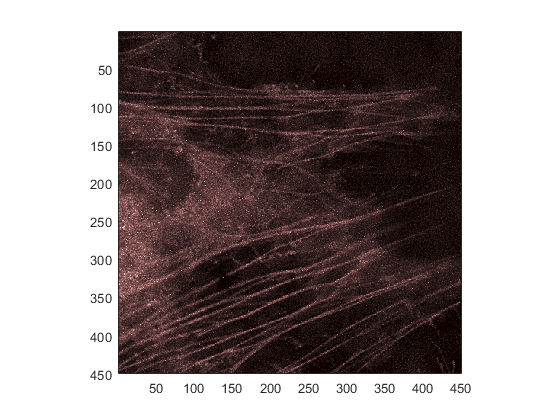


figure
imagesc(M6_LDRC(:,:,T))
axis square;
cmap = colormap(pink);

## save the result

save demo_result.mat M6_NF_DeconvSK_NF_LDRC ImMean_Series

## produce visualization of the result

for i0 = 1 : T
    im_in=ImMean_Series(:,:,i0);
    imwrite(im_in./max(im_in,[], 'all'), 'demo_input.tif', 'WriteMode','append');
    im_out = M6_LDRC(:, :, i0);
    imwrite((im_out./max(im_out, [],'all')), 'demo_output.tif', 'WriteMode','append');
end

Means_DeconvSK = zeros(xdim, ydim, T);
for i0 = 1 : T
    im = ImMean_Series(:, :, i0);
    % now prepare input parameters for xy_DeconvSk
        para.J0 = [im, fliplr(im); flipud(im), rot90(im,2)];% perform mirror extension to the image in order to surpress ringing artifacts associated with fourier transform due to truncation effect.
        para.PSF0 = fspecial('gaussian', [51,51], 2); % prepare an estimation of the convolution kernel here. In this datasets, cross-correlation doesn't work, therefore we use a rough estimation.
        para.lambda = 1.5; %DeconvSK parameter
        para.ItN = 20; % iteration number.
    disp(['calculating DeconvSK on image ',num2str(i0),'/',num2str(T),'...'])
    output = xy_DeconvSK(para);
    Means_DeconvSK(:, :, i0) = output(1:xdim, 1:ydim);
    im1=Means_DeconvSK(:,:,i0)./max(Means_DeconvSK(:,:,i0),[],'all');
    imwrite(im1, 'deconv_of_means.tif', 'WriteMode','append');
end

calculating DeconvSK on block 1/20...


im1 =     0.1281    0.1328    0.1376    0.1501    0.1393    0.1487    0.1503    0.1462    0.1442    0.1345    0.1563    0.1529    0.1453    0.1441    0.1402    0.1426    0.1472    0.1459    0.1495    0.1476    0.1506    0.1520    0.1543    0.1485    0.1610    0.1647    0.1776    0.1799    0.1716    0.1680    0.1642    0.1645    0.1799    0.1807    0.1799    0.1933    0.1768    0.1896    0.1912    0.1898    0.1873    0.1773    0.1912    0.1849    0.1922    0.1972    0.2019    0.2152    0.2513    0.2424
    0.1315    0.1403    0.1491    0.1464    0.1507    0.1468    0.1433    0.1412    0.1344    0.1421    0.1479    0.1574    0.1511    0.1500    0.1512    0.1524    0.1470    0.1481    0.1419    0.1591    0.1516    0.1560    0.1516    0.1587    0.1556    0.1684    0.1713    0.1894    0.1901    0.1854    0.1694    0.1844    0.2034    0.1929    0.2160    0.2017    0.1858    0.1912    0.2031    0.2161    0.2179    0.2142    0.2245    0.2220    0.2155    0.2229    0.2335    0.2404    0.2368   

calculating DeconvSK on block 2/20...


im1 =     0.1336    0.1277    0.1416    0.1335    0.1438    0.1506    0.1352    0.1275    0.1343    0.1316    0.1457    0.1510    0.1511    0.1512    0.1395    0.1436    0.1351    0.1434    0.1413    0.1484    0.1585    0.1596    0.1603    0.1574    0.1742    0.1678    0.1720    0.1708    0.1669    0.1685    0.1695    0.1788    0.1881    0.1876    0.1817    0.1745    0.1795    0.1773    0.1883    0.1849    0.1725    0.1754    0.1919    0.1906    0.1993    0.2007    0.2062    0.2277    0.2502    0.2561
    0.1357    0.1467    0.1442    0.1446    0.1479    0.1449    0.1343    0.1249    0.1499    0.1422    0.1450    0.1533    0.1476    0.1363    0.1559    0.1566    0.1521    0.1501    0.1521    0.1449    0.1519    0.1480    0.1460    0.1569    0.1524    0.1687    0.1671    0.1782    0.1902    0.1796    0.1799    0.1967    0.1885    0.1870    0.1922    0.2061    0.1939    0.1843    0.1983    0.2168    0.2210    0.2190    0.2184    0.2173    0.2140    0.2251    0.2395    0.2264    0.2363   

calculating DeconvSK on block 3/20...


im1 =     0.1294    0.1313    0.1372    0.1393    0.1282    0.1317    0.1344    0.1310    0.1318    0.1403    0.1410    0.1487    0.1435    0.1385    0.1403    0.1337    0.1424    0.1331    0.1354    0.1432    0.1493    0.1541    0.1451    0.1611    0.1565    0.1559    0.1740    0.1680    0.1779    0.1651    0.1681    0.1745    0.1730    0.1738    0.1693    0.1693    0.1728    0.1695    0.1691    0.1856    0.1822    0.1805    0.1813    0.1899    0.2069    0.2013    0.1860    0.2045    0.2229    0.2245
    0.1349    0.1354    0.1444    0.1360    0.1388    0.1413    0.1337    0.1325    0.1352    0.1399    0.1455    0.1435    0.1397    0.1405    0.1428    0.1348    0.1354    0.1352    0.1397    0.1437    0.1462    0.1566    0.1477    0.1550    0.1581    0.1673    0.1822    0.1736    0.1800    0.1817    0.1882    0.1910    0.1905    0.1762    0.1963    0.1934    0.1878    0.1939    0.1885    0.1879    0.2015    0.2226    0.2102    0.2146    0.2040    0.2147    0.2107    0.2212    0.2238   

calculating DeconvSK on block 4/20...


im1 =     0.1221    0.1359    0.1417    0.1461    0.1334    0.1416    0.1321    0.1301    0.1364    0.1317    0.1421    0.1352    0.1488    0.1557    0.1382    0.1383    0.1391    0.1515    0.1499    0.1461    0.1521    0.1559    0.1565    0.1545    0.1618    0.1630    0.1626    0.1810    0.1790    0.1689    0.1690    0.1765    0.1757    0.1729    0.1662    0.1730    0.1707    0.1787    0.1731    0.1854    0.1772    0.1778    0.1763    0.1952    0.1983    0.1904    0.2042    0.2168    0.2296    0.2247
    0.1379    0.1490    0.1398    0.1382    0.1390    0.1383    0.1311    0.1372    0.1359    0.1396    0.1423    0.1461    0.1559    0.1403    0.1393    0.1410    0.1431    0.1418    0.1449    0.1449    0.1491    0.1537    0.1502    0.1533    0.1644    0.1759    0.1723    0.1867    0.1921    0.1799    0.1804    0.1880    0.2023    0.2045    0.1950    0.1965    0.1879    0.1841    0.2085    0.2109    0.2161    0.2183    0.2132    0.2090    0.2122    0.2012    0.2162    0.2330    0.2292   

calculating DeconvSK on block 5/20...


im1 =     0.1205    0.1374    0.1393    0.1268    0.1273    0.1293    0.1253    0.1269    0.1227    0.1302    0.1472    0.1480    0.1406    0.1392    0.1298    0.1314    0.1375    0.1347    0.1367    0.1406    0.1309    0.1532    0.1382    0.1534    0.1575    0.1623    0.1578    0.1750    0.1692    0.1620    0.1709    0.1747    0.1659    0.1722    0.1612    0.1619    0.1599    0.1650    0.1721    0.1816    0.1804    0.1778    0.1816    0.1793    0.1859    0.1876    0.1873    0.1985    0.2187    0.2144
    0.1266    0.1377    0.1348    0.1375    0.1282    0.1308    0.1220    0.1242    0.1207    0.1270    0.1386    0.1445    0.1465    0.1319    0.1344    0.1450    0.1330    0.1477    0.1386    0.1442    0.1457    0.1447    0.1487    0.1539    0.1527    0.1678    0.1668    0.1773    0.1869    0.1743    0.1840    0.1778    0.1832    0.1852    0.1836    0.1849    0.1786    0.1756    0.1927    0.1993    0.2131    0.2192    0.2097    0.2068    0.2067    0.2138    0.2128    0.2300    0.2177   

calculating DeconvSK on block 6/20...


im1 =     0.1126    0.1366    0.1255    0.1310    0.1203    0.1220    0.1265    0.1304    0.1391    0.1339    0.1444    0.1461    0.1487    0.1478    0.1403    0.1332    0.1292    0.1359    0.1437    0.1355    0.1532    0.1537    0.1517    0.1474    0.1523    0.1621    0.1729    0.1669    0.1697    0.1811    0.1750    0.1727    0.1629    0.1726    0.1791    0.1739    0.1680    0.1687    0.1719    0.1802    0.1854    0.1793    0.1861    0.1908    0.1888    0.1894    0.1957    0.2084    0.2180    0.2270
    0.1361    0.1500    0.1394    0.1484    0.1371    0.1292    0.1324    0.1308    0.1353    0.1321    0.1441    0.1539    0.1409    0.1443    0.1360    0.1443    0.1395    0.1398    0.1475    0.1467    0.1566    0.1488    0.1447    0.1453    0.1646    0.1735    0.1796    0.1842    0.1835    0.1817    0.1777    0.1756    0.1780    0.1957    0.1884    0.1845    0.1847    0.1850    0.1841    0.1959    0.2046    0.2173    0.2219    0.2057    0.2072    0.1997    0.2102    0.2197    0.2173   

calculating DeconvSK on block 7/20...


im1 =     0.1247    0.1387    0.1381    0.1284    0.1188    0.1306    0.1293    0.1304    0.1288    0.1375    0.1375    0.1436    0.1510    0.1385    0.1377    0.1325    0.1354    0.1412    0.1462    0.1447    0.1386    0.1373    0.1418    0.1506    0.1568    0.1600    0.1675    0.1666    0.1694    0.1759    0.1760    0.1710    0.1684    0.1757    0.1819    0.1645    0.1763    0.1788    0.1852    0.1803    0.1883    0.1851    0.1784    0.1911    0.1879    0.1791    0.1846    0.1895    0.2114    0.2110
    0.1323    0.1434    0.1360    0.1294    0.1310    0.1330    0.1323    0.1365    0.1303    0.1331    0.1355    0.1415    0.1379    0.1372    0.1369    0.1397    0.1400    0.1455    0.1366    0.1441    0.1423    0.1439    0.1488    0.1534    0.1766    0.1832    0.1770    0.1688    0.1738    0.1774    0.1823    0.1917    0.1896    0.1966    0.1914    0.1894    0.1913    0.1748    0.1878    0.1877    0.2113    0.2210    0.2176    0.2123    0.2131    0.2020    0.2010    0.2052    0.2068   

calculating DeconvSK on block 8/20...


im1 =     0.1291    0.1358    0.1375    0.1357    0.1233    0.1341    0.1383    0.1338    0.1397    0.1301    0.1453    0.1432    0.1535    0.1543    0.1463    0.1550    0.1484    0.1459    0.1459    0.1426    0.1501    0.1480    0.1411    0.1532    0.1564    0.1711    0.1706    0.1596    0.1758    0.1816    0.1840    0.1775    0.1805    0.1842    0.1770    0.1716    0.1794    0.1876    0.1874    0.1826    0.1864    0.1868    0.1984    0.1997    0.1991    0.2014    0.1952    0.2100    0.2182    0.2166
    0.1365    0.1388    0.1379    0.1374    0.1346    0.1402    0.1412    0.1467    0.1432    0.1402    0.1526    0.1570    0.1482    0.1429    0.1422    0.1410    0.1483    0.1514    0.1449    0.1505    0.1536    0.1491    0.1423    0.1551    0.1749    0.1789    0.1735    0.1760    0.1889    0.1904    0.1864    0.1858    0.1978    0.2015    0.1981    0.1894    0.1856    0.1905    0.2075    0.2078    0.2169    0.2239    0.2173    0.2205    0.2044    0.2114    0.2134    0.2108    0.2081   

calculating DeconvSK on block 9/20...


im1 =     0.1234    0.1298    0.1348    0.1301    0.1304    0.1334    0.1432    0.1342    0.1268    0.1341    0.1420    0.1538    0.1592    0.1373    0.1441    0.1521    0.1487    0.1437    0.1490    0.1513    0.1421    0.1408    0.1521    0.1545    0.1575    0.1517    0.1647    0.1702    0.1737    0.1671    0.1729    0.1788    0.1804    0.1818    0.1739    0.1640    0.1609    0.1770    0.1737    0.1754    0.1864    0.1951    0.1946    0.1889    0.1925    0.1985    0.1877    0.1901    0.2088    0.2212
    0.1418    0.1426    0.1377    0.1350    0.1351    0.1431    0.1391    0.1331    0.1345    0.1417    0.1453    0.1496    0.1486    0.1372    0.1419    0.1537    0.1470    0.1421    0.1459    0.1459    0.1387    0.1428    0.1530    0.1577    0.1648    0.1692    0.1640    0.1708    0.1795    0.1863    0.1860    0.1884    0.1866    0.2058    0.1890    0.1805    0.1883    0.2038    0.1882    0.2120    0.2136    0.2265    0.2299    0.2271    0.2137    0.2043    0.1971    0.1939    0.1904   

calculating DeconvSK on block 10/20...


im1 =     0.1331    0.1431    0.1339    0.1425    0.1339    0.1303    0.1401    0.1429    0.1472    0.1423    0.1532    0.1522    0.1509    0.1603    0.1505    0.1379    0.1516    0.1406    0.1463    0.1469    0.1578    0.1509    0.1545    0.1463    0.1505    0.1628    0.1775    0.1669    0.1575    0.1687    0.1765    0.1639    0.1700    0.1738    0.1696    0.1756    0.1733    0.1722    0.1928    0.1862    0.1733    0.1889    0.1919    0.1884    0.1995    0.2025    0.1902    0.1977    0.2220    0.2276
    0.1279    0.1442    0.1347    0.1310    0.1309    0.1412    0.1381    0.1371    0.1371    0.1416    0.1499    0.1630    0.1535    0.1437    0.1409    0.1382    0.1486    0.1381    0.1459    0.1510    0.1495    0.1579    0.1619    0.1694    0.1649    0.1647    0.1772    0.1813    0.1808    0.1826    0.1926    0.1816    0.1930    0.1961    0.1908    0.1983    0.1979    0.2054    0.2102    0.2119    0.2201    0.2212    0.2264    0.2253    0.2253    0.2278    0.2147    0.2163    0.2169   

calculating DeconvSK on block 11/20...


im1 =     0.1342    0.1376    0.1316    0.1393    0.1337    0.1457    0.1402    0.1386    0.1428    0.1483    0.1575    0.1639    0.1514    0.1502    0.1454    0.1437    0.1370    0.1457    0.1459    0.1473    0.1525    0.1560    0.1749    0.1606    0.1607    0.1667    0.1637    0.1746    0.1587    0.1749    0.1691    0.1714    0.1642    0.1588    0.1735    0.1675    0.1709    0.1781    0.1824    0.1794    0.1822    0.1960    0.1939    0.1873    0.1993    0.2057    0.2057    0.2001    0.2305    0.2196
    0.1367    0.1354    0.1318    0.1380    0.1382    0.1427    0.1435    0.1432    0.1427    0.1468    0.1431    0.1479    0.1509    0.1480    0.1433    0.1381    0.1384    0.1475    0.1437    0.1561    0.1615    0.1561    0.1567    0.1648    0.1588    0.1735    0.1713    0.1786    0.1835    0.1905    0.2079    0.1959    0.1894    0.1990    0.1996    0.1993    0.1922    0.1967    0.2005    0.2049    0.2207    0.2246    0.2417    0.2235    0.2184    0.2184    0.2214    0.2120    0.2135   

calculating DeconvSK on block 12/20...


im1 =     0.1256    0.1401    0.1326    0.1300    0.1220    0.1363    0.1359    0.1375    0.1474    0.1441    0.1639    0.1533    0.1617    0.1426    0.1466    0.1350    0.1294    0.1453    0.1398    0.1378    0.1457    0.1496    0.1621    0.1505    0.1538    0.1547    0.1592    0.1596    0.1643    0.1629    0.1543    0.1794    0.1650    0.1806    0.1705    0.1628    0.1717    0.1722    0.1725    0.1763    0.1876    0.1746    0.1825    0.1938    0.2027    0.1956    0.1949    0.2106    0.2303    0.2337
    0.1351    0.1369    0.1330    0.1359    0.1393    0.1457    0.1370    0.1366    0.1301    0.1361    0.1475    0.1558    0.1649    0.1419    0.1431    0.1404    0.1359    0.1415    0.1464    0.1440    0.1509    0.1530    0.1485    0.1631    0.1640    0.1616    0.1689    0.1770    0.1914    0.1878    0.2007    0.1967    0.2024    0.1991    0.1922    0.1810    0.1913    0.2010    0.1981    0.2135    0.2213    0.2210    0.2346    0.2230    0.2153    0.2026    0.2082    0.2344    0.2285   

calculating DeconvSK on block 13/20...


im1 =     0.1294    0.1384    0.1337    0.1434    0.1376    0.1394    0.1361    0.1409    0.1457    0.1480    0.1592    0.1605    0.1603    0.1487    0.1492    0.1457    0.1453    0.1426    0.1523    0.1512    0.1420    0.1627    0.1738    0.1654    0.1449    0.1594    0.1555    0.1625    0.1789    0.1600    0.1673    0.1700    0.1641    0.1767    0.1548    0.1593    0.1735    0.1664    0.1846    0.1815    0.1804    0.1815    0.1697    0.2002    0.1895    0.1923    0.2086    0.2212    0.2214    0.2061
    0.1299    0.1435    0.1340    0.1385    0.1376    0.1315    0.1373    0.1336    0.1425    0.1367    0.1480    0.1607    0.1539    0.1528    0.1432    0.1364    0.1471    0.1453    0.1540    0.1555    0.1602    0.1648    0.1553    0.1569    0.1601    0.1697    0.1771    0.1808    0.1955    0.1936    0.2019    0.1976    0.1932    0.1958    0.1965    0.1961    0.2009    0.1915    0.2113    0.2134    0.2052    0.2071    0.2204    0.2303    0.2149    0.2105    0.2239    0.2331    0.2152   

calculating DeconvSK on block 14/20...


im1 =     0.1319    0.1483    0.1434    0.1413    0.1346    0.1429    0.1489    0.1493    0.1521    0.1466    0.1570    0.1576    0.1612    0.1590    0.1481    0.1379    0.1406    0.1513    0.1518    0.1498    0.1638    0.1667    0.1590    0.1625    0.1477    0.1563    0.1650    0.1636    0.1754    0.1634    0.1643    0.1633    0.1698    0.1717    0.1765    0.1691    0.1768    0.1792    0.1855    0.1860    0.1805    0.2051    0.1891    0.1963    0.1968    0.1967    0.2176    0.2229    0.2237    0.2278
    0.1338    0.1534    0.1474    0.1391    0.1375    0.1464    0.1413    0.1479    0.1481    0.1560    0.1656    0.1649    0.1526    0.1481    0.1445    0.1559    0.1504    0.1668    0.1582    0.1626    0.1550    0.1715    0.1609    0.1581    0.1633    0.1725    0.1747    0.1927    0.1998    0.2061    0.1995    0.2000    0.1973    0.1990    0.2006    0.1967    0.2060    0.1980    0.2098    0.2162    0.2171    0.2126    0.2169    0.2302    0.2268    0.2177    0.2152    0.2250    0.2217   

calculating DeconvSK on block 15/20...


im1 =     0.1356    0.1551    0.1487    0.1496    0.1518    0.1481    0.1537    0.1608    0.1650    0.1540    0.1613    0.1652    0.1627    0.1642    0.1544    0.1478    0.1472    0.1580    0.1532    0.1572    0.1702    0.1756    0.1667    0.1564    0.1688    0.1742    0.1752    0.1771    0.1667    0.1591    0.1618    0.1565    0.1688    0.1767    0.1608    0.1777    0.1739    0.1765    0.1796    0.1973    0.1936    0.1942    0.1942    0.2077    0.1987    0.1896    0.2063    0.2230    0.2424    0.2359
    0.1461    0.1462    0.1430    0.1486    0.1371    0.1483    0.1398    0.1457    0.1507    0.1590    0.1593    0.1598    0.1561    0.1559    0.1539    0.1480    0.1506    0.1563    0.1505    0.1525    0.1622    0.1768    0.1723    0.1612    0.1647    0.1891    0.1880    0.2075    0.2108    0.2119    0.2167    0.2065    0.2125    0.2188    0.2114    0.1946    0.2038    0.2097    0.2075    0.2184    0.2171    0.2374    0.2477    0.2418    0.2185    0.2259    0.2174    0.2349    0.2251   

calculating DeconvSK on block 16/20...


im1 =     0.1433    0.1500    0.1547    0.1558    0.1528    0.1680    0.1643    0.1747    0.1732    0.1664    0.1692    0.1775    0.1712    0.1724    0.1625    0.1528    0.1518    0.1626    0.1654    0.1597    0.1613    0.1789    0.1744    0.1619    0.1668    0.1710    0.1832    0.1724    0.1780    0.1698    0.1694    0.1786    0.1823    0.1781    0.1759    0.1722    0.1811    0.1829    0.1820    0.1788    0.1985    0.2059    0.1961    0.2099    0.2140    0.2185    0.2176    0.2317    0.2447    0.2569
    0.1591    0.1498    0.1550    0.1446    0.1560    0.1636    0.1516    0.1561    0.1628    0.1612    0.1695    0.1666    0.1703    0.1662    0.1554    0.1553    0.1634    0.1637    0.1693    0.1699    0.1697    0.1730    0.1837    0.1731    0.1769    0.2027    0.2106    0.2115    0.2080    0.2113    0.2183    0.2103    0.2203    0.2301    0.2122    0.2124    0.2017    0.2115    0.2181    0.2202    0.2364    0.2373    0.2476    0.2458    0.2344    0.2352    0.2399    0.2442    0.2413   

calculating DeconvSK on block 17/20...


im1 =     0.1401    0.1632    0.1671    0.1618    0.1701    0.1633    0.1648    0.1700    0.1604    0.1705    0.1700    0.1699    0.1699    0.1802    0.1666    0.1690    0.1601    0.1568    0.1698    0.1606    0.1675    0.1791    0.1863    0.1789    0.1713    0.1742    0.1779    0.1755    0.1659    0.1740    0.1698    0.1723    0.1765    0.1966    0.1919    0.1791    0.1823    0.1924    0.1796    0.1922    0.1825    0.1875    0.2053    0.2012    0.2080    0.2061    0.2094    0.2330    0.2465    0.2434
    0.1572    0.1626    0.1570    0.1521    0.1614    0.1610    0.1567    0.1603    0.1627    0.1650    0.1740    0.1732    0.1628    0.1551    0.1599    0.1724    0.1693    0.1632    0.1665    0.1763    0.1808    0.1858    0.1796    0.1754    0.1770    0.1983    0.2023    0.2198    0.2122    0.2172    0.2187    0.2158    0.2127    0.2210    0.2173    0.2016    0.2086    0.2228    0.2258    0.2252    0.2340    0.2350    0.2674    0.2398    0.2394    0.2349    0.2365    0.2568    0.2533   

calculating DeconvSK on block 18/20...


im1 =     0.1382    0.1596    0.1651    0.1676    0.1599    0.1744    0.1665    0.1720    0.1662    0.1729    0.1659    0.1582    0.1557    0.1580    0.1696    0.1478    0.1437    0.1599    0.1700    0.1592    0.1680    0.1685    0.1693    0.1631    0.1780    0.1762    0.1660    0.1619    0.1569    0.1536    0.1713    0.1606    0.1701    0.1771    0.1810    0.1876    0.1897    0.1879    0.1846    0.1731    0.1812    0.1965    0.1944    0.1891    0.1965    0.1965    0.2179    0.2303    0.2382    0.2418
    0.1493    0.1585    0.1542    0.1606    0.1518    0.1457    0.1554    0.1484    0.1659    0.1825    0.1705    0.1721    0.1707    0.1674    0.1556    0.1577    0.1546    0.1637    0.1673    0.1707    0.1851    0.1758    0.1757    0.1789    0.1820    0.1922    0.1987    0.2005    0.2028    0.2023    0.2119    0.2145    0.2048    0.2202    0.2148    0.2069    0.2098    0.2217    0.2205    0.2199    0.2310    0.2407    0.2540    0.2347    0.2233    0.2299    0.2374    0.2563    0.2514   

calculating DeconvSK on block 19/20...


im1 =     0.1453    0.1648    0.1636    0.1638    0.1588    0.1625    0.1688    0.1715    0.1578    0.1751    0.1717    0.1665    0.1682    0.1613    0.1679    0.1635    0.1506    0.1449    0.1443    0.1554    0.1569    0.1677    0.1703    0.1692    0.1747    0.1764    0.1672    0.1613    0.1729    0.1707    0.1538    0.1622    0.1555    0.1748    0.1754    0.1825    0.1934    0.1762    0.1740    0.1773    0.1773    0.1771    0.1899    0.2060    0.1856    0.1956    0.2017    0.2117    0.2097    0.2241
    0.1548    0.1649    0.1565    0.1611    0.1514    0.1577    0.1574    0.1635    0.1673    0.1698    0.1733    0.1667    0.1704    0.1822    0.1806    0.1636    0.1666    0.1637    0.1670    0.1791    0.1890    0.1803    0.1685    0.1708    0.1849    0.1866    0.1783    0.1964    0.2099    0.1999    0.2029    0.2055    0.2126    0.2025    0.2009    0.2122    0.2148    0.2132    0.2169    0.2264    0.2298    0.2499    0.2588    0.2440    0.2360    0.2309    0.2373    0.2398    0.2456   

calculating DeconvSK on block 20/20...


im1 =     0.1437    0.1566    0.1581    0.1634    0.1469    0.1557    0.1702    0.1519    0.1514    0.1585    0.1562    0.1542    0.1493    0.1486    0.1507    0.1521    0.1411    0.1431    0.1491    0.1463    0.1522    0.1718    0.1683    0.1612    0.1659    0.1706    0.1573    0.1497    0.1650    0.1525    0.1537    0.1505    0.1653    0.1730    0.1681    0.1711    0.1891    0.1844    0.1784    0.1657    0.1782    0.1841    0.1779    0.1829    0.1980    0.2027    0.2059    0.2074    0.2146    0.2246
    0.1459    0.1507    0.1421    0.1464    0.1536    0.1552    0.1511    0.1553    0.1572    0.1692    0.1602    0.1592    0.1562    0.1690    0.1617    0.1661    0.1639    0.1596    0.1691    0.1752    0.1750    0.1824    0.1874    0.1745    0.1840    0.1886    0.1845    0.1922    0.1947    0.1898    0.1796    0.1921    0.2047    0.2074    0.1968    0.1948    0.2075    0.2196    0.2209    0.2089    0.2255    0.2418    0.2448    0.2345    0.2312    0.2263    0.2443    0.2414    0.2622   